# Trabajo practico N°8

# Controladores PID

### Ejercicio 1

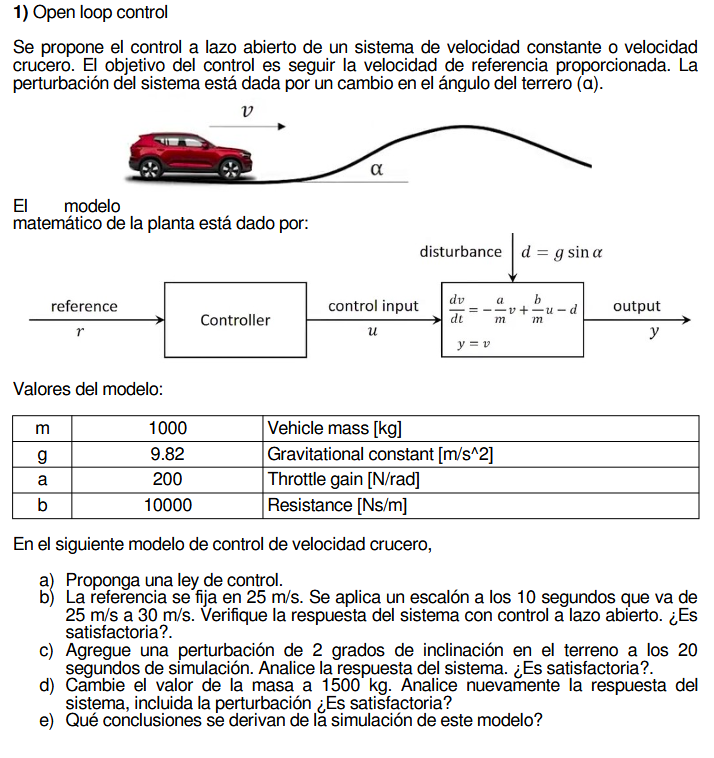

Se realiza una modificacion del modelo de la planta, ya que el análisis dimensional no es consistente, por lo que el modelo de la planta es:


$$\frac{dv}{dt}=-\frac{b}{m}v+\frac{a}{m}u-d\\
y=v$$
 

Cuando se requiere de una velocidad crucero, esta debe ser *constante* por lo tanto, para comenzar formulamos la ecuacion de la planta en estado estacionario

syms m g a b v u r d alpha t
eqn = 0 == -(b/m)*v + (a/m)*u;
u_control = solve(eqn,u);
u_control

$$u\_control = \frac{b\,v}{a}$$

Luego, la velocidad es justamente nuestra referencia

eqn = 0 == -(b/m)*r + (a/m)*u;
u_control = solve(eqn,u);
u_control

$$u\_control = \frac{b\,r}{a}$$

Lo queda una ley de control de tipo: $u=K_{ol}\cdot r$

m = 1000;   % Masa [kg]
g = 9.82;   % Gravedad [m/s^2]
a = 200;    % Ganancia del acelerador [N/rad] 
b = 10000;  % Resistencia [Ns/m]

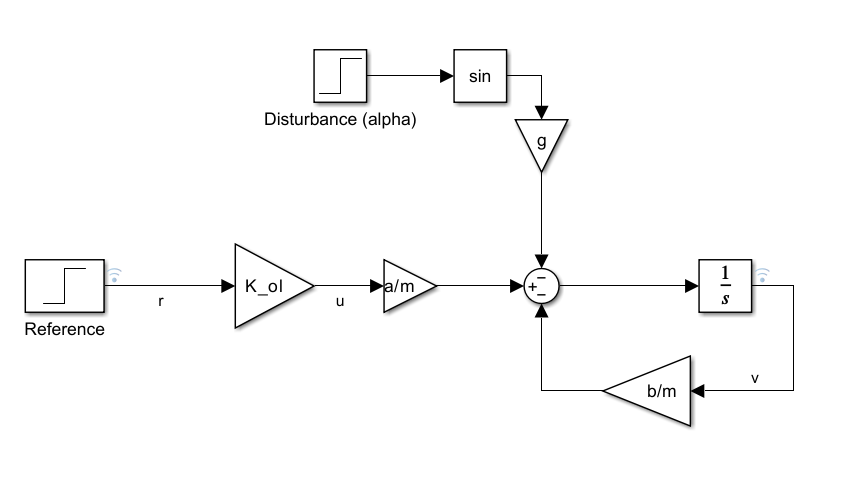

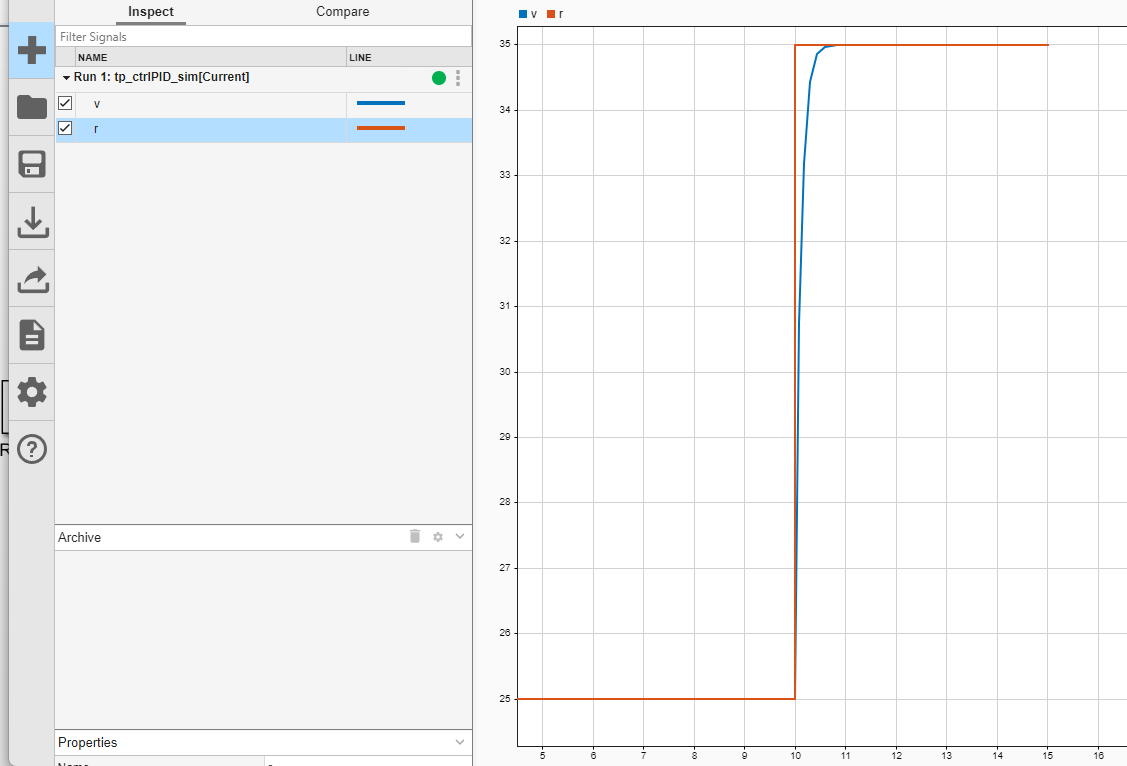

Si, es satisfactoria, ya que termina estableciendose en la velocidad requerida.

Luego aplicando la perturbación:

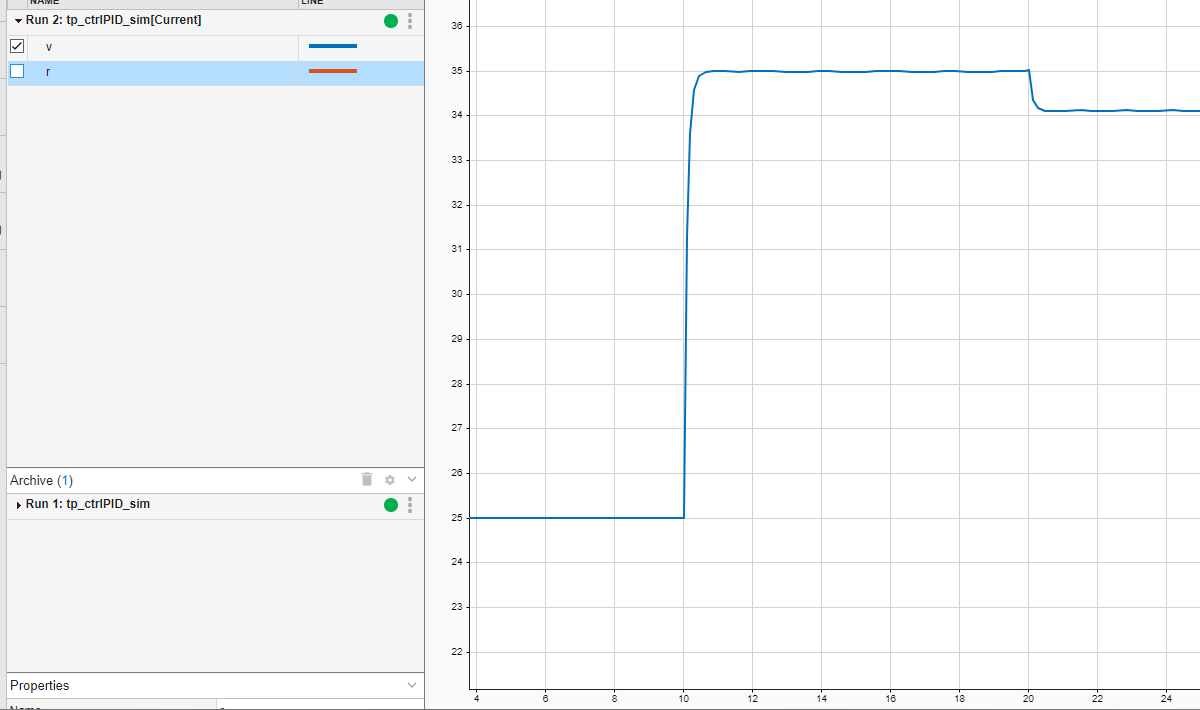

Evidentemente no es satisfactoria, dado que no hay realimentación.

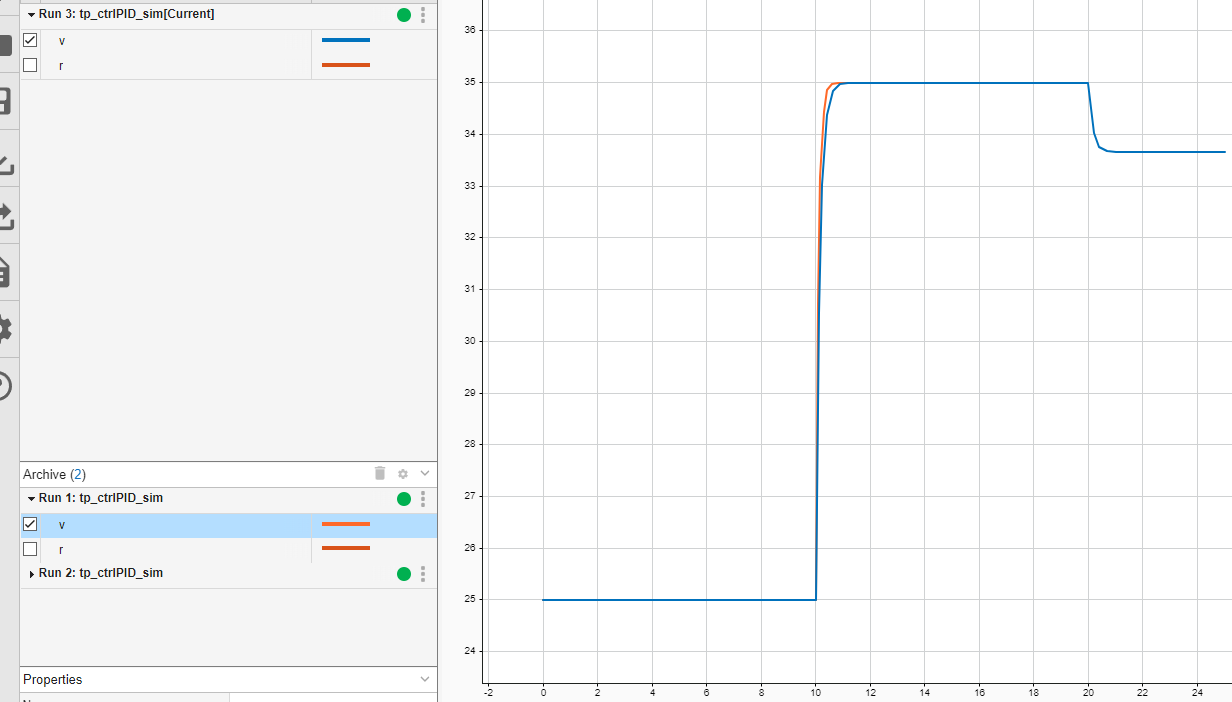

Sigue sin ser satisfactoria, solo que demora más en establecerse (azul)

#### Conclusión

Como conclusión se puede obtener que la ausencia de realimentación de la velocidad evita que el controlador pueda ajustar frente a perturbaciones que no se pueden "ver" desde la simple ley de control implementada.

### Ejercicio 2

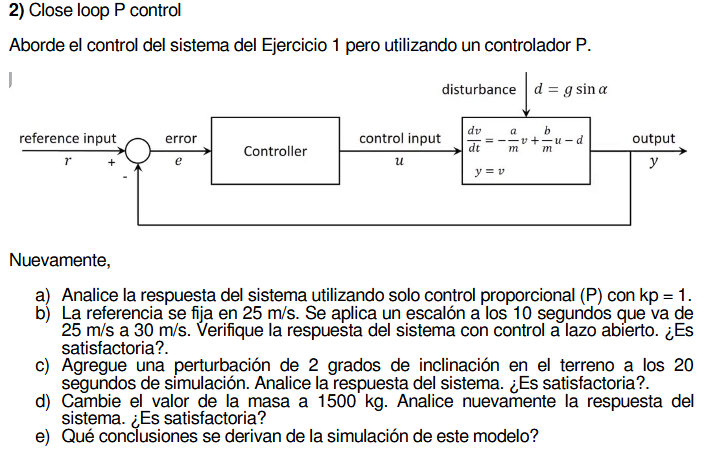

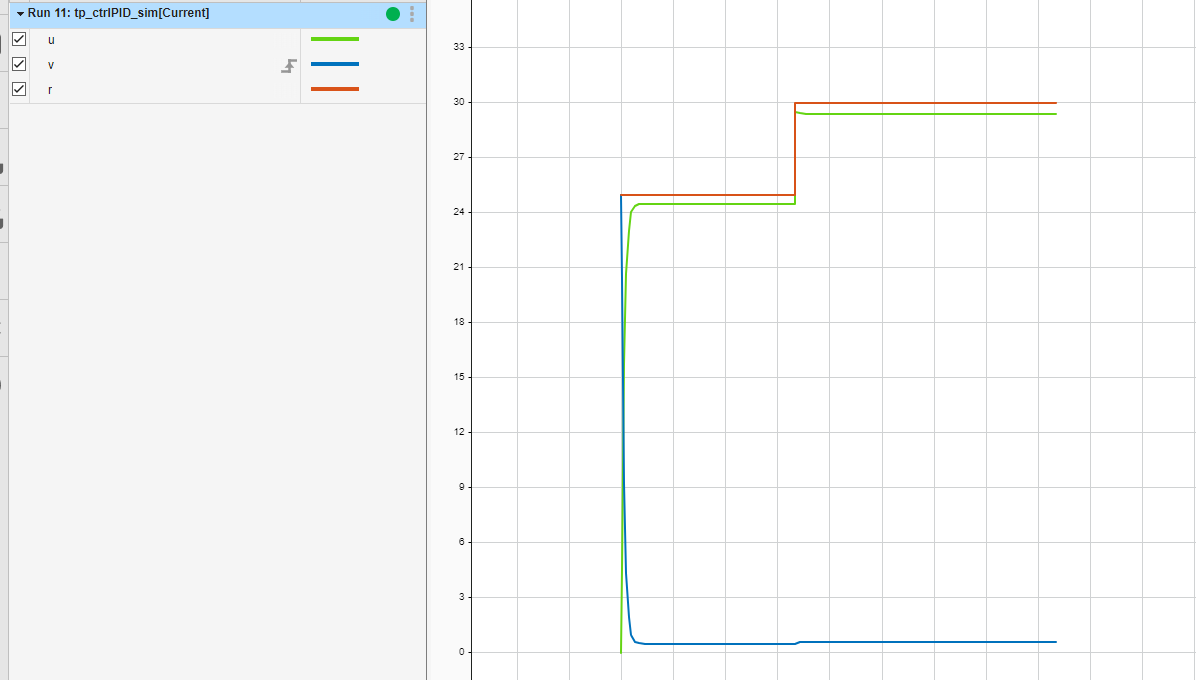

La respuesta no es satisfactoria con o sin el escalon de perturbación, esto es por la presencia de un error de estado estacionario.

### Ejercicio 3

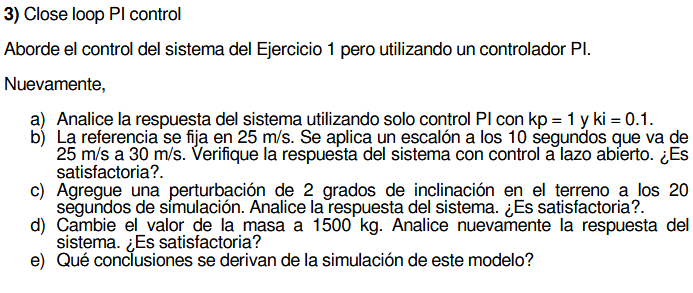

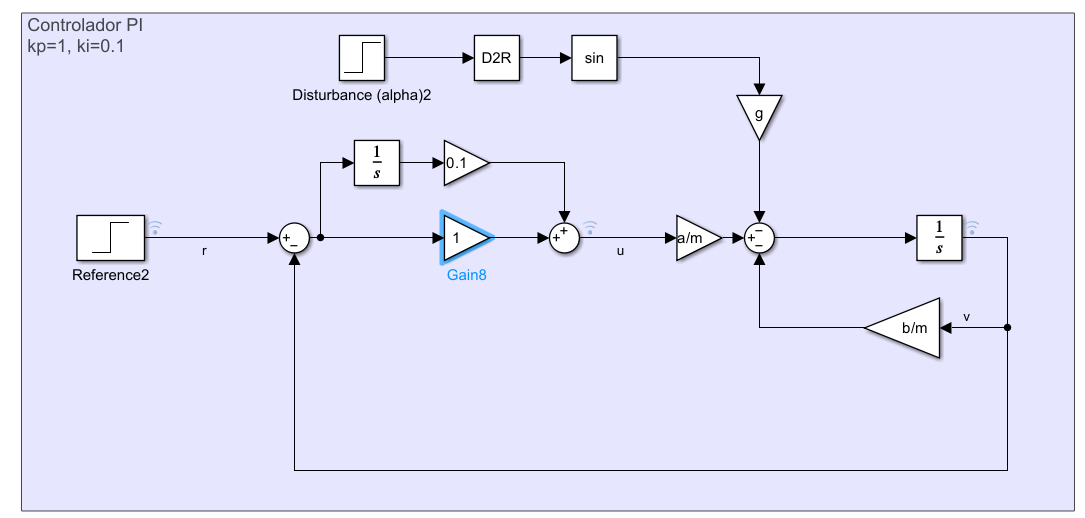

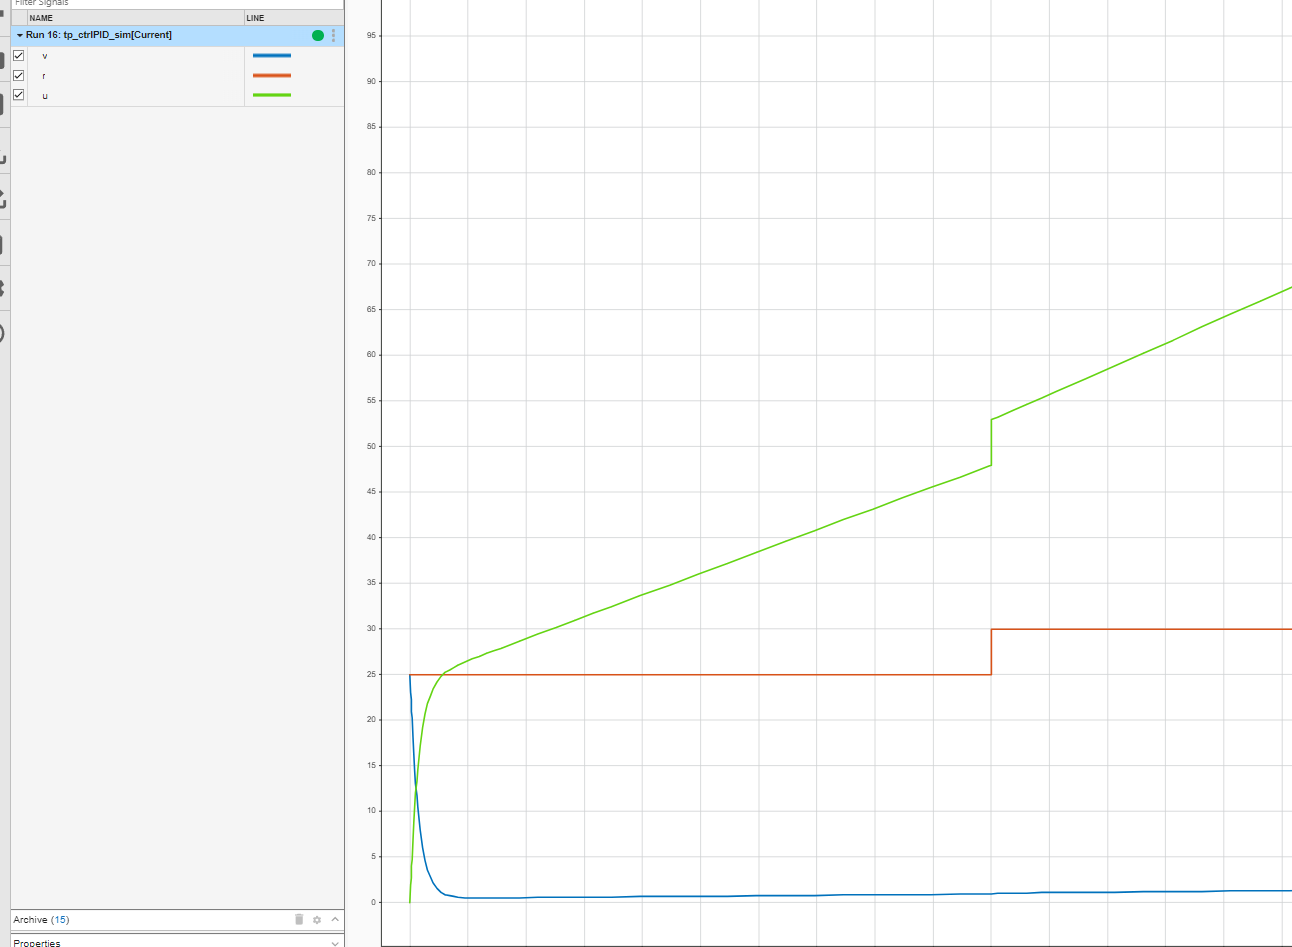

No es satisfactoria, en este caso por una mala sintonización de las ganancias.

### Ejercicio 4

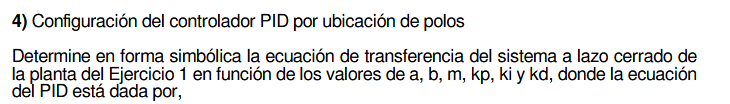

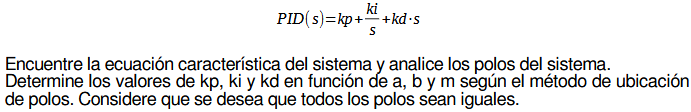

clear;
syms s a b m kp ki kd p real


$$G(s)=\frac{Y(s)}{U(s)}=\frac{a}{ms+b}
$$


G = a/(m*s+b);


$$PID(s) = k_p + \frac{k_i}{s}+k_ds
$$



$$C(s)=\frac{k_ps+k_i+k_ds^2}{s}$$


C = (kp*s+ki+kd*s^2)/s;


$$T(s)=\frac{Y(s)}{R(s)}=\frac{C(s)G(s)}{1+C(s)G(s)}$$


T = simplify((C*G)/(1+C*G));
disp("Transferencia en lazo cerrado: T(s)")

Transferencia en lazo cerrado: T(s)


pretty(T)

               2
        a (kd s  + kp s + ki)
------------------------------------
                2                  2
a ki + b s + m s  + a kp s + a kd s




[numT,denT]=numden(T);
denT = collect(denT,s);
coef_s2 = coeffs(denT, s, 'All');
coef_s2 = coef_s2(1);
disp("Ecuacion caracteristica: ")

Ecuacion caracteristica: 


pretty(denT == 0)

            2
(m + a kd) s  + (b + a kp) s + a ki == 0



Para el polinomio deseado


$$p_{des}=(s+p)^2
$$


pol_caracteristico_norm = simplify(denT/coef_s2);
pol_caracteristico_norm = collect(pol_caracteristico_norm,s);
disp("Ecuacion deseada: ")

Ecuacion deseada: 


p_des = s^2+2*p*s+p^2

$$p\_des = p^{2}+2\,p\,s+s^{2}$$

pretty(pol_caracteristico_norm == p_des)

 2   (b + a kp) s     a ki       2            2
s  + ------------ + -------- == p  + 2 p s + s
       m + a kd     m + a kd



Ahora igualamos coeficientes para encontrar kp, ki y kd en funcion de p

Hacemos la diferencia de los polinomios

pol_diff = expand(pol_caracteristico_norm - p_des);
pol_diff = collect(pol_diff,s);

%Igualamos coeficientes de potencias iguales
coef_diff = coeffs(pol_diff, s,'All');
eqs = coef_diff == 0;
disp("Ecuaciones al igualar coeficientes:");

Ecuaciones al igualar coeficientes:


pretty(eqs);

/     b              a kp           a ki      2      \
| -------- - 2 p + -------- == 0, -------- - p  == 0 |
\ m + a kd         m + a kd       m + a kd           /




sol = solve(eqs, [kp, ki]);
kp_sol = simplify(sol.kp)

$$kp\_sol = \frac{2\,m\,p-b+2\,a\,\mathrm{kd}\,p}{a}$$

ki_sol = simplify(sol.ki)

$$ki\_sol = \frac{p^{2}\,\left(m+a\,\mathrm{kd}\right)}{a}$$